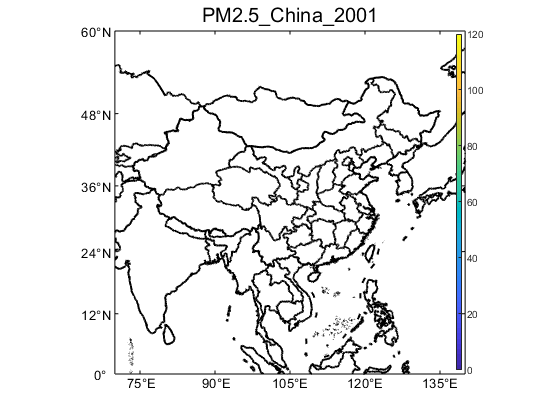

clc
clear
close all;
World = shaperead('F:\matlab\bin\App_Desgin\world map china line\world map china line.shp');
wx = [World(:).X];wy = [World(:).Y];%读取世界地图的shp文件
%中国省界线文件（含九段线）
ChinaL=shaperead('F:\matlab\bin\App_Desgin\全国省级、地市级、县市级行政区划shp\全国省级、地市级、县市级行政区划shp\bou2_4l.shp');
%中国面文件
ChinaP=shaperead('F:\matlab\bin\App_Desgin\全国省级、地市级、县市级行政区划shp\全国省级、地市级、县市级行政区划shp\bou2_4p.shp');
bou2_4lx=[ChinaL(:).X];
bou2_4ly=[ChinaL(:).Y];
bou2_4px=[ChinaP(:).X];
bou2_4py=[ChinaP(:).Y];

figure(1)
m_proj('miller','lon',[70,140],'lat',[0,60]);
% m_pcolor(Lon,Lat,A1);
hold on;
m_plot(bou2_4lx,bou2_4ly,'k','linewidth',1.5);%绘制中国省界
hold on;
m_plot(wx,wy,'k','linewidth',1.5,'color',[0 0 0]);%绘制中国以外的国家，有国界
shading interp;
% colormap(CM_bl2ye2re(2:end-1,:));%自己定义的colormap
m_grid('linestyle','none');
%m_coast('linewidth',1.5,'color',[.4 .4 .4]);%绘制中国以外的国家，没有国界
title('PM2.5_China_2001','fontsize',15,'interpreter','none');
axes('position',[.7,.12,.2,.80]);%设置colorbar的位置
axis off
caxis([0 120]);
colorbar('ticks',[0:20:120]);

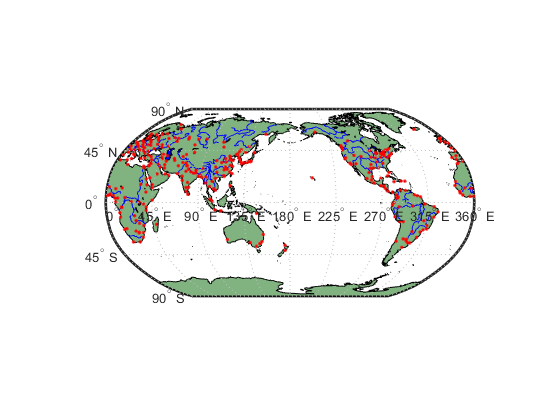

clc
clear
close all

% ax=worldmap('china'); %worldmap命令生成一个map axis，其各项属性可以用getm(ax)来获得
% setm(ax,'grid','off') % 关闭grid，其实就是经线和纬线
% setm(ax,'frame','off') % 关闭边框
% setm(ax,'parallellabel','off') % 关闭坐标轴标记，相当于X轴
% setm(ax,'meridianlabel','off') % 关闭坐标轴标记，相当于Y轴

% 创建世界地图坐标区域
ax=worldmap('World');
setm(ax,'Origin',[0 180 0])

% 绘制陆地
land=shaperead('landareas.shp','UseGeoCoords',true);
geoshow(ax,land,'FaceColor',[0.5 0.7 0.5])
% 绘制湖泊
lakes=shaperead('worldlakes.shp','UseGeoCoords',true);
geoshow(lakes,'FaceColor','blue')
% 绘制河流
rivers=shaperead('worldrivers.shp','UseGeoCoords',true);
geoshow(rivers, 'Color', 'blue')
% 绘制城市
cities=shaperead('worldcities.shp','UseGeoCoords',true);
geoshow(cities,'Marker','.','Color','red')

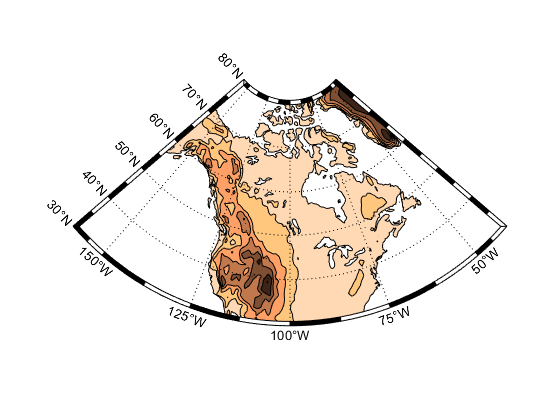

clc
clear
close all
m_proj('lambert','long',[-160 -40],'lat',[30 80]);
m_coast('patch',[1 .85 .7]);
m_elev('contourf',[500:500:6000]);
m_grid('box','fancy','tickdir','in');
colormap(flipud(copper));

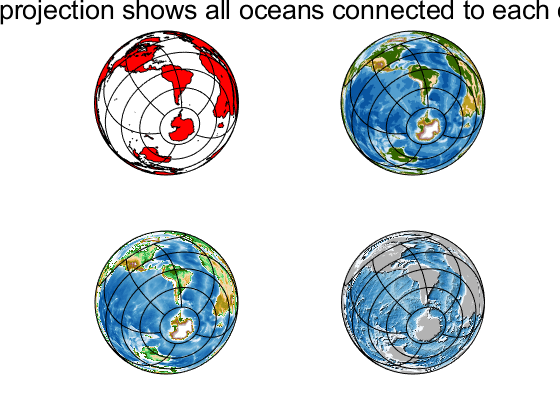

clc
clear 
close all
m_proj('azimuthal equal-area','radius',156,'lat',-46,'long',-95,'rot',30);

     ax1=subplot(2,2,1,'align');
      m_coast('patch','r');
      m_grid('xticklabel',[],'yticklabel',[],'linestyle','-','ytick',[-60:30:60]);
        
     ax2=subplot(2,2,2,'align');
      m_elev('contourf',[-7000:1000:0 500:500:3000],'edgecolor','none');
      colormap(ax2,[m_colmap('blues',70);m_colmap('gland',30)]);  
      caxis(ax2,[-7000 3000]);       
      m_grid('xticklabel',[],'yticklabel',[],'linestyle','-','ytick',[-60:30:60]);

        
     ax3=subplot(2,2,3,'align');
      colormap(ax3,[m_colmap('blues',70);m_colmap('gland',30)]);  
      caxis(ax3,[-7000 3000]);       
      m_elev('image');
      m_grid('xticklabel',[],'yticklabel',[],'linestyle','-','ytick',[-60:30:60]);

        
     ax4=subplot(2,2,4,'align');
      colormap(ax4,[m_colmap('blues')]);  
      caxis(ax4,[-8000 000]);       
      m_elev('shadedrelief','gradient',.5);
      m_coast('patch',[.7 .7 .7],'edgecolor','none');
      m_grid('xticklabel',[],'yticklabel',[],'linestyle','-','ytick',[-60:30:60]);

     ha = axes('Position',[0 0 1 1],'Xlim',[0 1],'Ylim',[0  1],'Box','off',...
               'Visible','off','Units','normalized', 'clipping' , 'off');
      text(0.5, 0.98,'This projection shows all oceans connected to each other',...
               'horiz','center','fontsize',20);

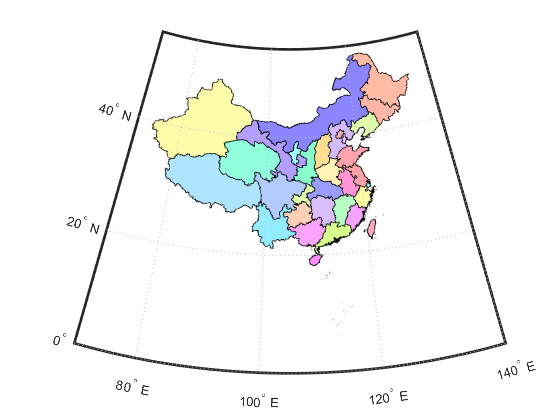

clc
clear
close all

provinces=shaperead('bou2_4p.shp','UseGeoCoords',true);

% 绘图
worldmap('China');
faceColors=makesymbolspec('Polygon',{'INDEX',[1 numel(provinces)],'FaceColor',polcmap(numel(provinces))});
geoshow(provinces,'DisplayType','polygon','SymbolSpec',faceColors)

clc
clear
close all
provinces=shaperead('bou2_4p.shp','UseGeoCoords',true);

% 插值定义颜色
C=[222,238,209;126,190,174;144,213,220;
    33,118,155;30,69,128;20,49,127]./255;
C1(:,1)=interp1(0:5,C(:,1),linspace(0,5,numel(provinces)),'linear')';
C1(:,2)=interp1(0:5,C(:,2),linspace(0,5,numel(provinces)),'linear')';
C1(:,3)=interp1(0:5,C(:,3),linspace(0,5,numel(provinces)),'linear')';

% 绘图
worldmap('China');
faceColors=makesymbolspec('Polygon',{'INDEX',[1 numel(provinces)],'FaceColor',C1});
geoshow(provinces,'DisplayType','polygon','SymbolSpec',faceColors)

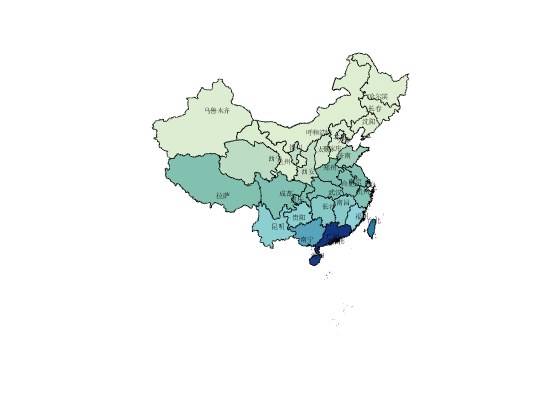

clc
clear
close all
provinces=shaperead('bou2_4p.shp','UseGeoCoords',true);

% 插值定义颜色
C=[222,238,209;126,190,174;144,213,220;
    33,118,155;30,69,128;20,49,127]./255;
C1(:,1)=interp1(0:5,C(:,1),linspace(0,5,numel(provinces)),'linear')';
C1(:,2)=interp1(0:5,C(:,2),linspace(0,5,numel(provinces)),'linear')';
C1(:,3)=interp1(0:5,C(:,3),linspace(0,5,numel(provinces)),'linear')';

% 绘图
ax=worldmap('China');
faceColors=makesymbolspec('Polygon',{'INDEX',[1 numel(provinces)],'FaceColor',C1});
geoshow(provinces,'DisplayType','polygon','SymbolSpec',faceColors)

% 读取首都和省级行政中心位置信息并标记
pnames=shaperead('res1_4m.shp','UseGeoCoords',true);
for i=1:numel(pnames)
    textm(pnames(i).Lat,pnames(i).Lon,pnames(i).NAME, ...
   'HorizontalAlignment','center','FontSize',5,'color','k')
end
setm(ax,'grid','off') % 关闭grid，其实就是经线和纬线
setm(ax,'frame','off') % 关闭边框
setm(ax,'parallellabel','off') % 关闭坐标轴标记，相当于X轴
setm(ax,'meridianlabel','off') % 关闭坐标轴标记，相当于Y轴

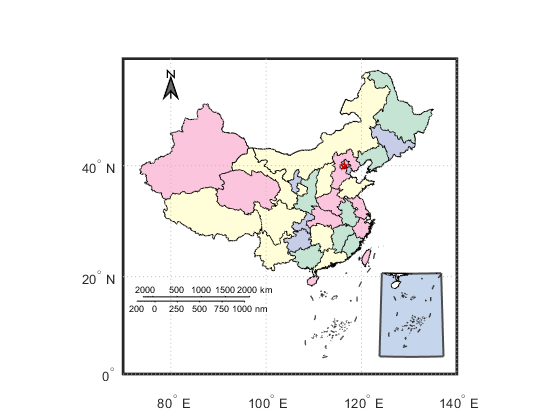

clc
clear
close all
ax=worldmap('china');
setm(ax,'mapprojection','mercator');

% 绘制国界
bordersl=shaperead('bou1_4l.shp','UseGeoCoords',true);
geoshow(bordersl,'Color',[.3,.3,.3],'LineWidth',1)
% 绘制省份
colorList=[197,228,212;255,254,216;251,197,221;199,205,231]./255;
colorList=repmat(colorList,[250,1]);
provinces=shaperead('bou2_4p.shp','UseGeoCoords',true);
colorList=colorList(1:numel(provinces),:);
faceColors=makesymbolspec('Polygon',{'INDEX',[1 numel(provinces)],'FaceColor',colorList});
geoshow(provinces,'DisplayType','polygon','SymbolSpec',faceColors)

% 首都
pnames=shaperead('res1_4m.shp','UseGeoCoords',true);
geoshow(pnames(1).Lat,pnames(1).Lon,'DisplayType','point','Marker','p',...
    'MarkerEdgeColor',[.8,0,0],'MarkerFaceColor',[.8,0,0])

% 指北针
northarrow('latitude',50,'longitude',80,'scaleratio',.08,'FaceColor',[.4,.4,.4])

% 比例尺
scaleruler on
setm(handlem('scaleruler1'), ...
    'XLoc',-3.2e6,'YLoc',1.8e6, ...
    'MajorTick',0:500:2000,...
    'MinorTick',0:40:200,'FontSize',7)
scaleruler('units','nm')
setm(handlem('scaleruler2'), ...
    'XLoc',-3.15e6, ...
    'YLoc',1.7e6, ...
    'TickDir','down', ...
    'MajorTick',0:250:1000,...
    'MinorTick',0:40:200,...
    'MajorTickLength',km2nm(25),...
    'MinorTickLength',km2nm(12.5),'FontSize',7)

% 小地图
h2=axes('pos',[0.67 0.15 0.13 0.2]);
worldmap([1 22],[106 122])
setm(h2,'FFaceColor',[197,213,236]./255,'FEdgeColor',[.3,.3,.3],'FLineWidth',1.5)
insert1=shaperead('bou2_4l.shp','UseGeoCoords',true);
geoshow(insert1,'Color',[.2,.2,.2],'LineWidth',1)
insert2=shaperead('bou2_4p.shp','UseGeoCoords',true);
geoshow(insert2,'FaceColor','w')
mlabel off 
plabel off
gridm off

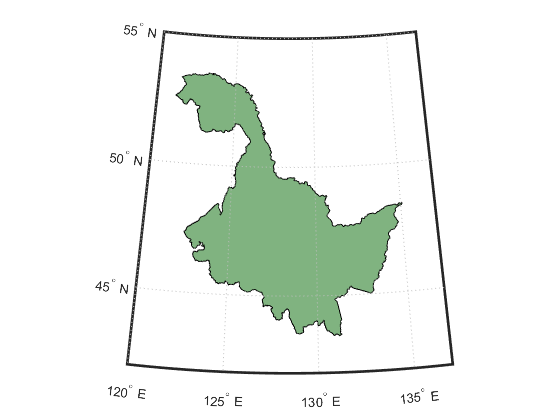


clc
clear
close all

worldmap([42,55],[120,137]);

% 从中国省份数据文件中获取黑龙江省
P=shaperead('bou2_4p.shp','UseGeoCoords',true,...
  'Selector',{@(name) strcmp(name,'黑龙江省'),'NAME'});
patchm(P.Lat,P.Lon, [0.5 0.7 0.5])

clc
clear
close all

sheng=shaperead('bou2_4p.shp', 'UseGeoCoords', true); % 省
load F:\matlab\bin\App_Desgin\china_map1\chinese_name.mat % 省，省会，主要城市的正确中文
for i=1:length(sheng)
    sheng(i).NAME=sheng_chinese_name{i}; % 纠正中文显示错误
end
unique(sheng_chinese_name) % 含有34个省（直辖市）的数据

ans = 34×1 cell 数组
    {'上海市'        }
    {'云南省'        }
    {'内蒙古自治区'   }
    {'北京市'        }
    {'台湾省'        }
    {'吉林省'        }
    {'四川省'        }
    {'天津市'        }
    {'宁夏回族自治区' }
    {'安徽省'        }
    {'山东省'        }
    {'山西省'        }
    {'广东省'        }
    {'广西壮族自治区' }
    {'新疆维吾尔自治区'}
    {'江苏省'        }
    {'江西省'        }
    {'河北省'        }
    {'河南省'        }
    {'浙江省'        }
    {'海南省'        }
    {'湖北省'        }
    {'湖南省'        }
    {'甘肃省'        }
    {'福建省'        }
    {'空'           }
    {'西藏自治区'    }
    {'贵州省'        }
    {'辽宁省'        }
    {'重庆市'        }
    {'陕西省'        }
    {'青海省'        }
    {'香港特别行政区' }
    {'黑龙江省'      }


length(sheng) % 共分为925个区块

ans =    925


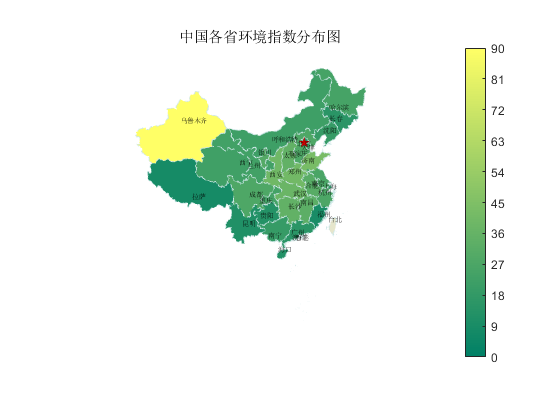


d=importdata('F:\matlab\bin\App_Desgin\EnvironmentRange.txt');
data=d.data; % 人口数目
textdata=d.textdata; % 相对应的省的名称

k=128;
mycolormap=summer(k);
% 生成不同区域按大小的颜色，按照人口数目多少分别指定不同的颜色
% 人口越多，颜色越突出
geoname={sheng.NAME}';
max_data = max(data);
n=length(data);
mysymbolspec=cell(1,n);% 预定义变量可以加快处理速度
for i=1:n
    count=data(i);
    mycoloridx=floor( k * count / max_data );
    mycoloridx(mycoloridx<1)=1;
    myprovince=textdata{i};
    geoidx=strmatch(myprovince, geoname);
    if numel(geoidx) > 0
        province_name=geoname( geoidx(1) );
        mysymbolspec{i} = {'NAME', char(province_name), 'FaceColor', mycolormap( mycoloridx, :) };
    end
end

figure
ax=worldmap('china'); % 使用worldmap的坐标轴作图
setm(ax,'grid','off') % 关闭grid
setm(ax,'frame','off') % 关闭边框
setm(ax,'parallellabel','off') % 关闭坐标轴标记
setm(ax,'meridianlabel','off') % 关闭坐标轴标记

% 最关键的两个语句
symbols=makesymbolspec('Polygon',{'default','FaceColor',[0.9 0.9 0.8],...
    'LineStyle','--','LineWidth',0.2,...
    'EdgeColor',[0.8 0.9 0.9]},...
    mysymbolspec{:}...
    );
geoshow(sheng,'SymbolSpec',symbols); % 此处用mapshow投影会不正确

% 在图像右侧显示bar
colormap(summer(k))
hcb=colorbar('EastOutside');
step=round(max_data/11);
set(hcb,'YTick',(0:.1:1))
set(hcb,'YTickLabel',num2cell(0:step:max_data))

% 给图像加标题
% 首都
pnames=shaperead('res1_4m.shp','UseGeoCoords',true);
geoshow(pnames(1).Lat,pnames(1).Lon,'DisplayType','point','Marker','p',...
    'MarkerEdgeColor',[.8,0,0],'MarkerFaceColor',[.8,0,0])

% 读取首都和省级行政中心位置信息并标记
pnames=shaperead('res1_4m.shp','UseGeoCoords',true);
for i=1:numel(pnames)
    textm(pnames(i).Lat,pnames(i).Lon,pnames(i).NAME, ...
   'HorizontalAlignment','center','FontSize',5,'color','k')
end

% % 小地图
% h2=axes('pos',[0.67 0.15 0.13 0.2]);
% worldmap([1 22],[106 122])
% setm(h2,'FFaceColor',[197,213,236]./255,'FEdgeColor',[.3,.3,.3],'FLineWidth',1.5)
% insert1=shaperead('bou2_4l.shp','UseGeoCoords',true);
% geoshow(insert1,'Color',[.2,.2,.2],'LineWidth',1)
% insert2=shaperead('bou2_4p.shp','UseGeoCoords',true);
% geoshow(insert2,'FaceColor','w')
% mlabel off 
% plabel off
% gridm off

title('中国各省环境指数分布图')